# Solutions for Brain states exercises

Solutions for exercises in brainstates.mlx for computer practical Neurophysics course

Available at [https://github.com/heimel/Brainstates](https://github.com/heimel/Brainstates)

2024, Alexander Heimel

### Solution Data.1

plot(spike_times{1},1:length(spike_times{1}));
xlim(recording_interval);
xlabel('Time (s)');
ylabel('Spike count');

### Solution Data.2

all_spikes = sort(vertcat(spike_times{:}));  
plot(all_spikes,1:length(all_spikes));
xlim(recording_interval);
xlabel('Time (s)');
ylabel('Spike count');


### Solution Data.3

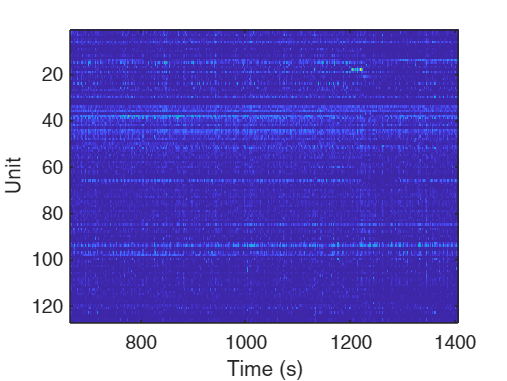

figure
imagesc(bin_counts,'XData',bin_times)
xlabel('Time (s)')
ylabel('Unit')

### Solution Data.4

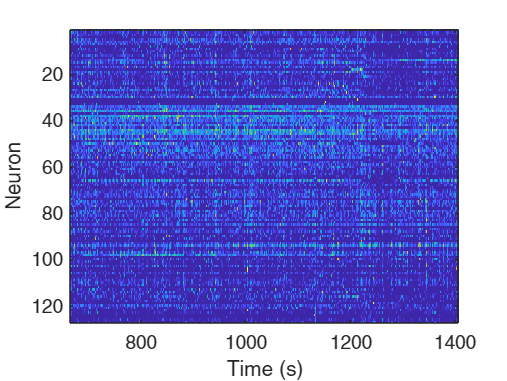

bin_counts_norm = bin_counts ./ max(bin_counts,[],2);
imagesc(bin_counts_norm,'XData',bin_times)
xlabel('Time (s)')
ylabel('Neuron')

### Solution PCA.1

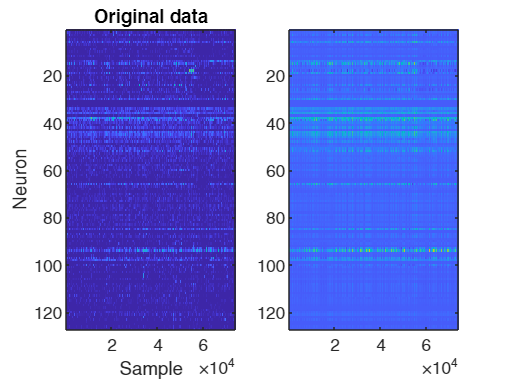

x_reconstruct = score(:,(1:3))*coeff(:,(1:3))' + repmat(x_mean,n_bins,1);
imagesc(x_reconstruct')

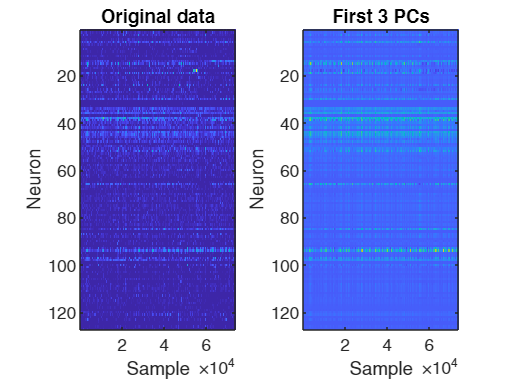


figure
subplot(1,2,1)
imagesc(x')
ylabel('Neuron')
xlabel('Sample')
title('Original data')

subplot(1,2,2)
imagesc(x_reconstruct')
ylabel('Neuron')
xlabel('Sample')
title('First 3 PCs')

### Solution FA.1

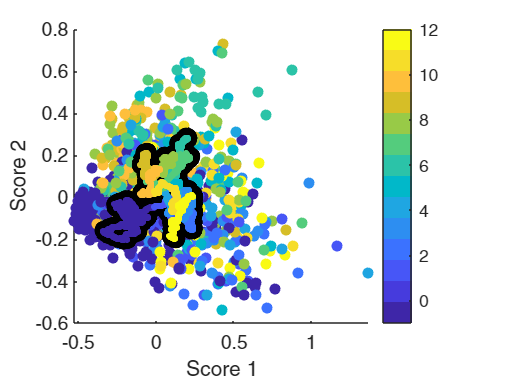

figure
scatter(score(ind_bin_subset,1),score(ind_bin_subset,2),30,bin_labels(ind_bin_subset),'filled')
colormap(parula(max(bin_labels(ind_bin_subset))+2))
axis square
colorbar
xlabel('Score 1')
ylabel('Score 2')
hold on

% Plot moving average
[~,ind] = sort(bin_labels);
x = movmean(score(ind,1),2000);
y = movmean(score(ind,2),2000);
plot(x,y,'k-','linewidth',10)
scatter(x,y,10,bin_labels(ind),'filled')

### Solution Tsne.1

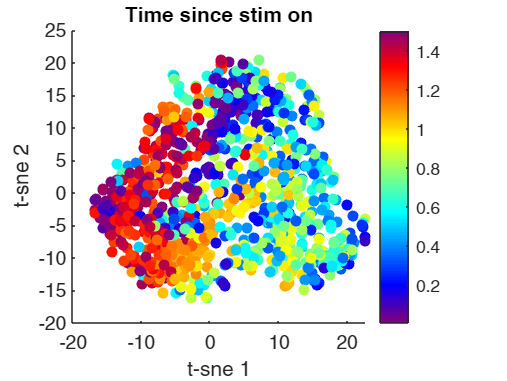

rng(1)
ind_bin_subset_cleaned = ind_bin_subset(idx_subset~=1);
x_tsne_cleaned = tsne(bin_counts(:,ind_bin_subset_cleaned)');

figure
c = bin_times_rel(ind_bin_subset_cleaned)';
scatter(x_tsne_cleaned(:,1),x_tsne_cleaned(:,2),30,c,'filled')
colormap(periodic_colormap(128))
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colorbar
title('Time since stim on')

### Solution GM.1

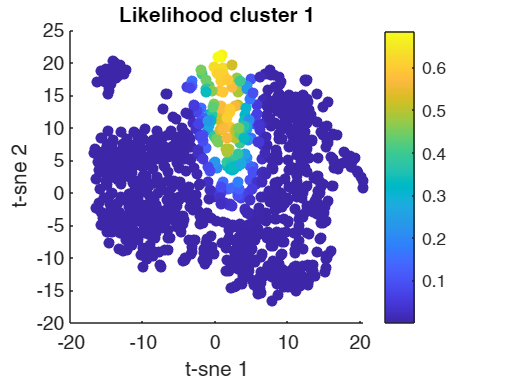

figure
scatter(x_tsne(:,1),x_tsne(:,2),30,post(:,1),'filled')
axis square
xlabel('t-sne 1')
ylabel('t-sne 2')
colorbar
title('Likelihood cluster 1')